#### General parameters 

These are the same 'options' used for the filtering and segmentation

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

#### Heart rate extraction from ABP (not used anymore)

Uses difference between location of abp beats

Cannot be used since prediction cannot use features from ABP waveform

% abp_beat_locs = importdata("../physionet.org/segmented_abp_beats/3000393_0016-0022b.txt");
% 
% [hr_avg, hr_max, hr_most_rec] = heartRateFromABP(abp_beat_locs, opts.samp_freq)


#### Heart Rate extraction from PPG

First the beat locations are extracted

Then these are used to find the HR (mean, max, most recent)

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0011.txt");
beat_locs = beatLocsFromPPG(data(:,3), 220, opts.samp_freq, 'systolic');
[hr_avg, hr_max, hr_most_rec] = heartRateFromBeatLocs(beat_locs, opts.samp_freq)

hr_avg = 74.3586

hr_max = 170.4545

hr_most_rec = 68.8073

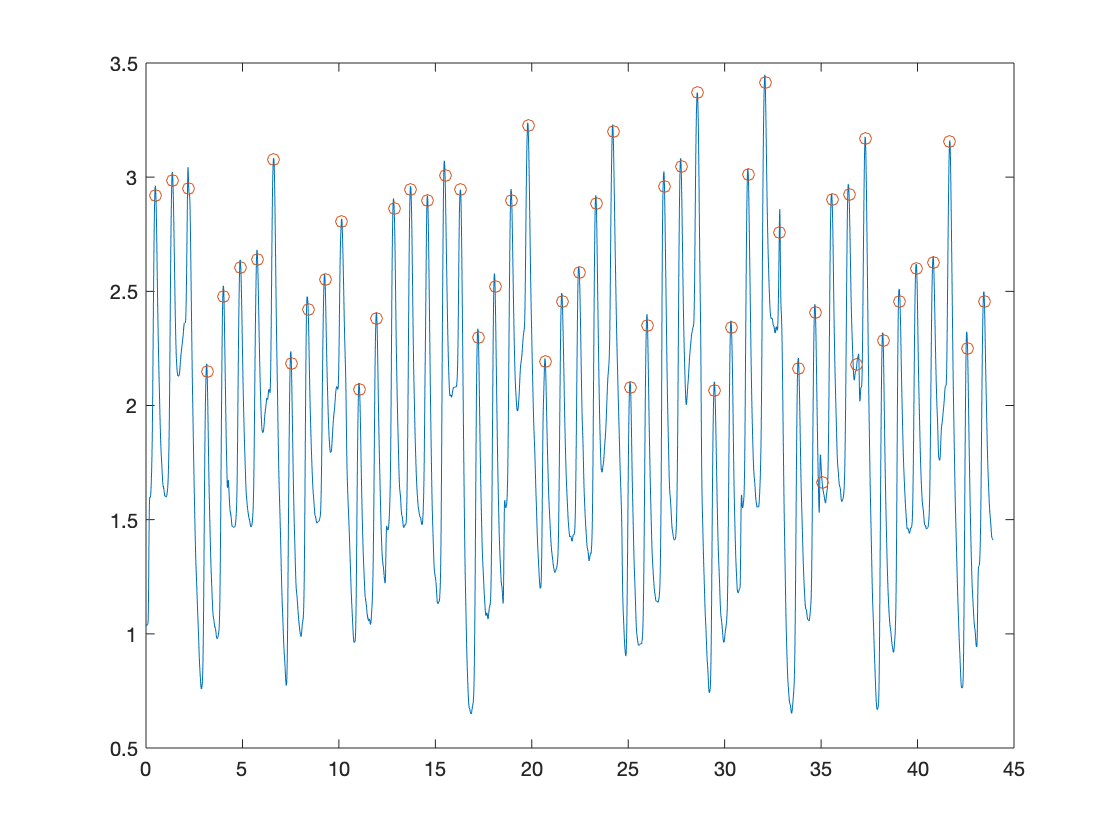

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(beat_locs,1), data(beat_locs,3))

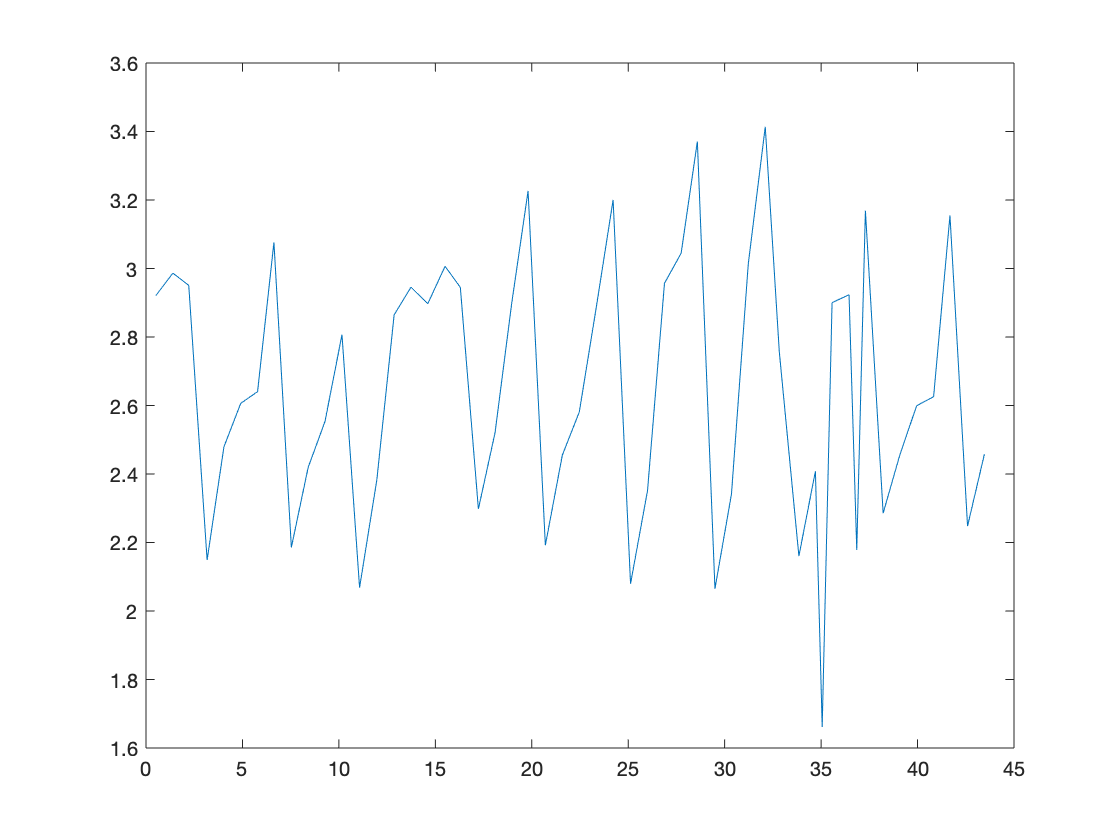

clf
plot(data(beat_locs,1), data(beat_locs,3))

#### Respiratory rate from PPG

See P.S.Addison et al. [https://sci-hub.se/10.1007/s10877-011-9332-y](https://sci-hub.se/10.1007/s10877-011-9332-y)

Typical freq range of respiration is [2.97;28.02] breaths/min <=> [0.05;0.47] Hz. A heart rate of [45;220] bpm <=> [0.75; 3.67] Hz ie. signals should be able to be separated

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0015-0009.txt");


resp_rate = getRespiratoryRateFreq(data(:,1), data(:,3))

resp_rate = 0.2619

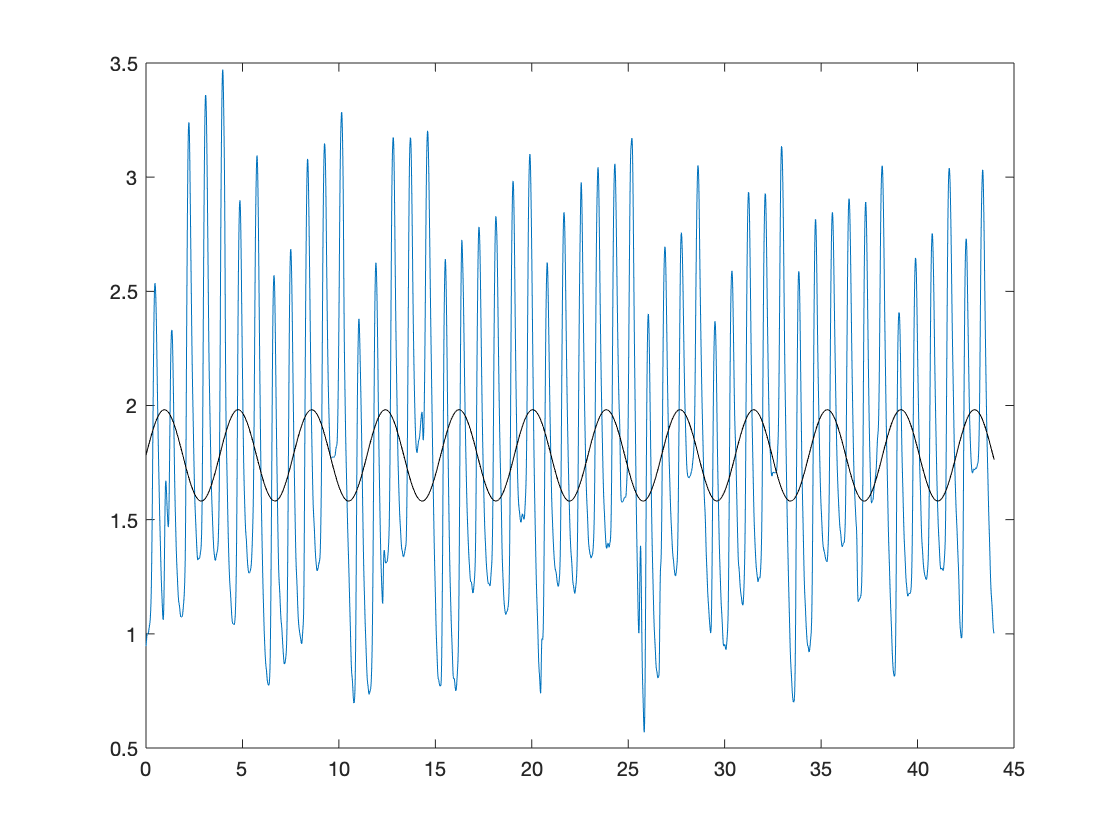


clf
plot(data(:,1), data(:,3))
hold on
plot(data(:,1), 0.2.*sin(2*pi*resp_rate.*data(:,1))+mean(data(:,3)), 'Color', 'black')

#### Systolic and Diastolic Peak Amplitudes

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3000393_0016-0009.txt");
[systolic_pts, mean_amp, dev_amp, max_amp, min_amp] = peakAmplitudes(...
    data(:,3),opts.samp_freq, 'systolic');
disp('Systolic Points')

Systolic Points


mean_amp

mean_amp = 2.6942

dev_amp

dev_amp = 0.3472

max_amp

max_amp = 3.3519

min_amp

min_amp = 2.0726


disp('Diastolic Pts')

Diastolic Pts


[diastolic_pts, mean_amp, dev_amp, max_amp, min_amp] = peakAmplitudes(...
    data(:,3),opts.samp_freq, 'diastolic');
mean_amp

mean_amp = 1.3721

dev_amp

dev_amp = 0.4182

max_amp

max_amp = 2.2055

min_amp

min_amp = 0.6464

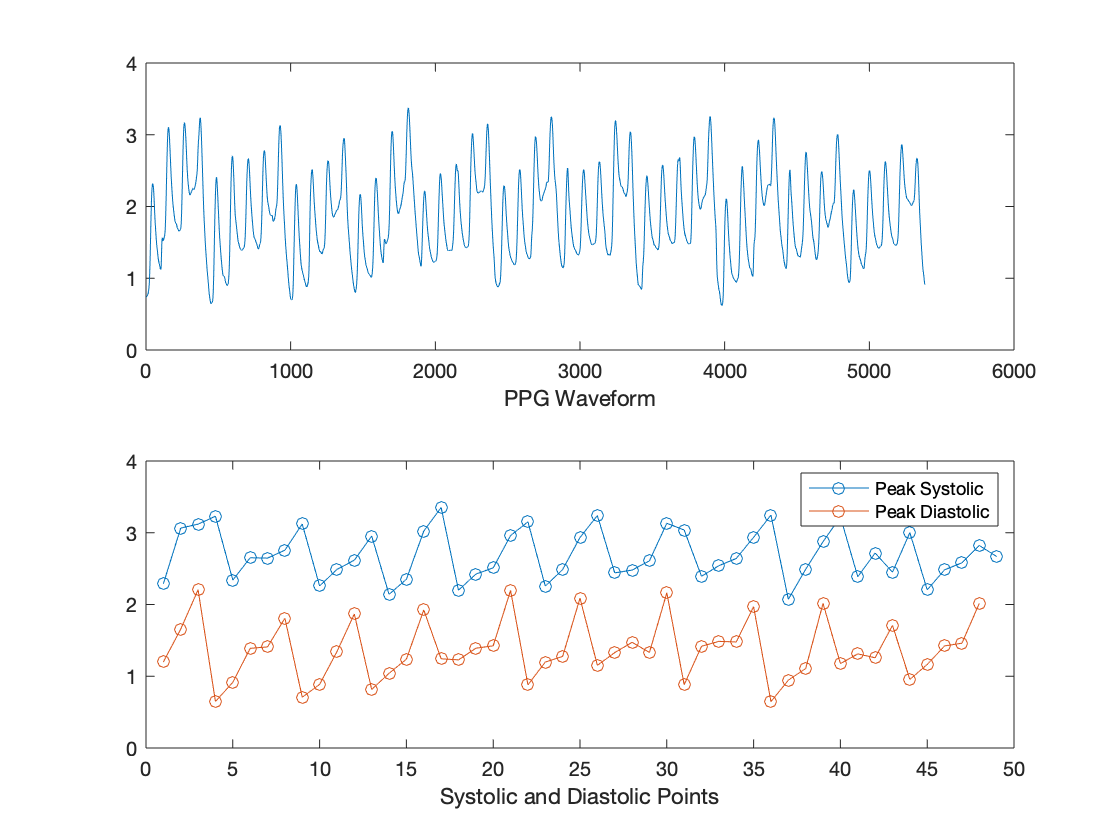


clf
subplot(2,1,1)
plot(data(:,3))
xlabel('PPG Waveform')
ylim([0,4]);
subplot(2,1,2)
plot(systolic_pts, 'o-')
hold on
plot(diastolic_pts, 'o-')
xlabel('Systolic and Diastolic Points')
legend('Peak Systolic', 'Peak Diastolic')
ylim([0,4]);

#### Systolic and Diastolic Time Intervals

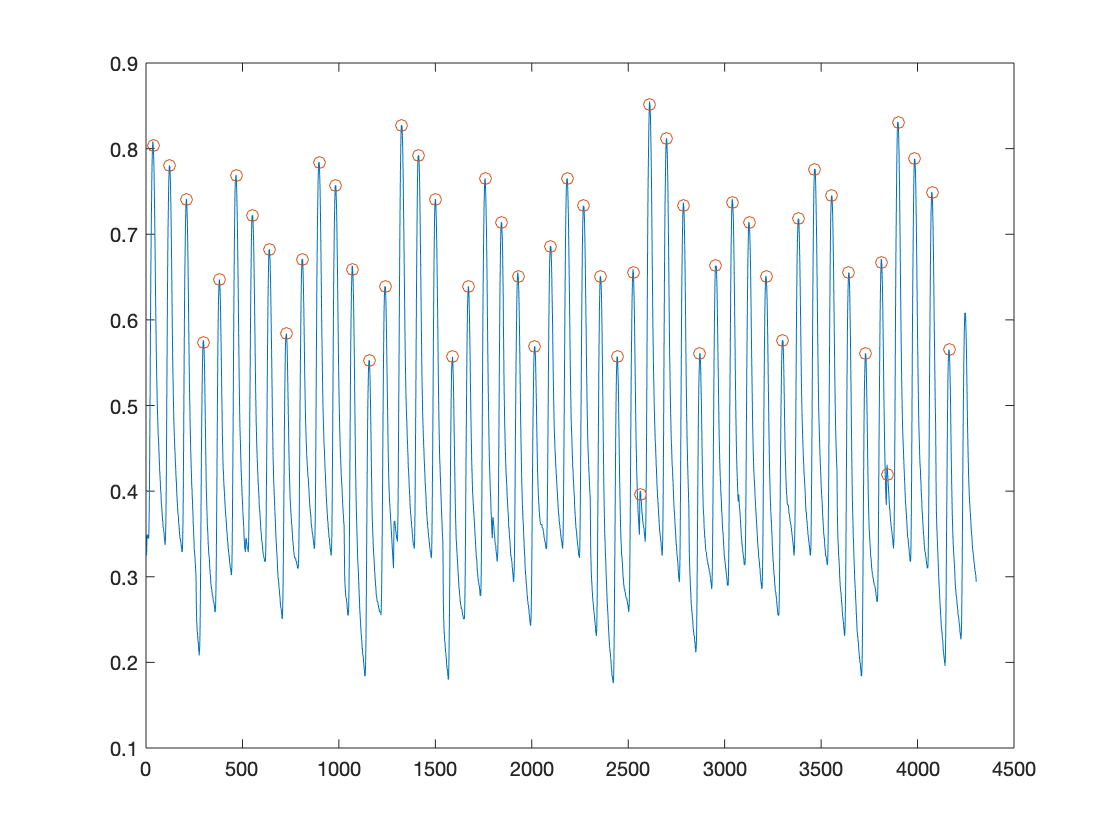

addpath('./TimeFeatures')
data = importdata("../physionet.org/segmented_data/3739816_0016-0006.txt");

findSystolicPeaks(data(:,3));

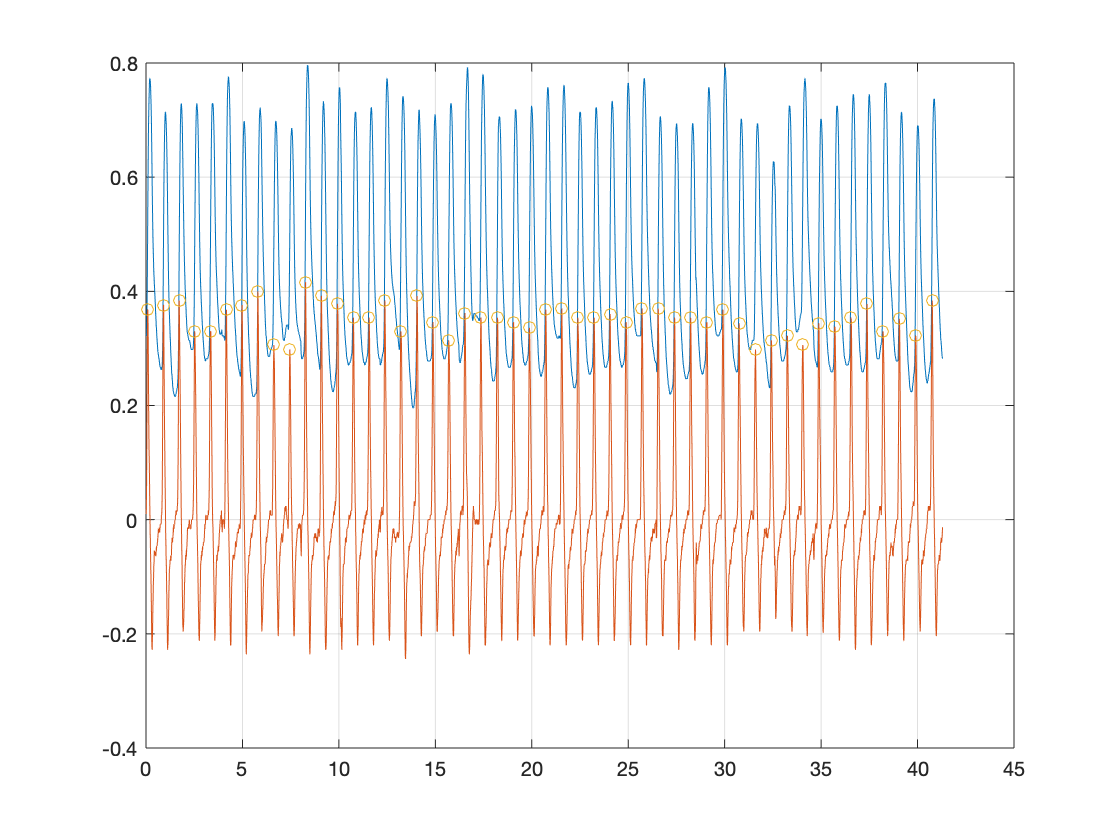


beats = find(islocalmax(data(:,3))==1);

clf
plot(data(:,1), data(:,3))
hold on
grid on
one_diff = diff(data(:,3));
one_diff = 10.*movmean(one_diff, 5);
[env_1] = envelope(one_diff,5, 'peaks');

sec_diff = diff(diff(data(:,3)));
sec_diff = 50.*movmean(sec_diff, 10);
[~, env_2] = envelope(sec_diff,5, 'peaks');
% plot(data(1:end-2,1), 10.*diff(diff(data(:,3))))
% plot(data(1:end-1,1), 10.*diff(data(:,3)))
plot(data(2:end,1), one_diff)
[pks, indices] = findpeaks(one_diff, 'MinPeakHeight', 0.1, 'MinPeakDistance', 30 );
scatter(data(indices,1), pks)

% plot(data(1:end-1,1), env_1, '-k', 'LineWidth',1)
% scatter(data(beats,1), data(beats,3))


function [freqVector, freqSpectrum] = singlesidedFFT(timeVector, timeSignal)
   n = length(timeVector);
   dT = mean(diff(timeVector));
   df = 1/dT;
   %freqVector = (-n/2:(n/2-1))* (df/n);
   freqVector = (0:(n/2 -1)) * (df/n);
   freqSpectrum = fft(timeSignal)/df;
   freqSpectrum(floor(n/2)+1 : end) = [];
   freqSpectrum(2:end) = freqSpectrum(2:end) * 2;
end

function [freqVector, freqSpectrum] = doublesidedFFT(timeVector, timeSignal)
   n = length(timeVector);
   dT = mean(diff(timeVector));
   df = 1/dT;
   freqVector = (-n/2:(n/2-1))* (df/n);
   freqSpectrum = fftshift(fft(timeSignal))/df;
end


